## Datastores

Create image datastore

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset (Augmented)\AugmentedAlzheimerDataset'
imds = imageDatastore(file_dataset_train, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset (Augmented)\OriginalDataset'
imdsTest = imageDatastore(file_dataset_train, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

## Split dataset

[imdsTrain, imdsValidate, ~] = splitEachLabel(imds, 0.1, 0.03, "randomized");
[imdsTest, ~] = splitEachLabel(imdsTest, 0.15, "randomized");

## Create resnet-50 network

Define classes

classNames = categories(imdsTrain.Labels)

classNames = 4×1 cell array
    {'MildDemented'    }
    {'ModerateDemented'}
    {'NonDemented'     }
    {'VeryMildDemented'}


numClasses = numel(classNames)

numClasses = 4

Create net using resnet-50 network

net = imagePretrainedNetwork('vgg19', NumClasses=numClasses)

Error using doImagePretrainedNetwork (line 48)
vgg19 requires the Deep Learning Toolbox Model for VGG-19 Network support package for the pretrained weights. To install this support package, use the Add-On Explorer. To obtain the untrained layers, use imagePretrainedNetwork("vgg19",Weights="none"), which does not require the support package.

Error in imagePretrainedNetwork (<a hr

## Convert the image into resnet-50 image input type

Input_Layer_Size = net.Layers(1).InputSize(1:2);

augimdsTrain = augmentedImageDatastore(Input_Layer_Size, imdsTrain);
augimdsValidate = augmentedImageDatastore(Input_Layer_Size, imdsValidate);
augimdsTest = augmentedImageDatastore(Input_Layer_Size, imdsTest);

## Train the network

Set up options

options = trainingOptions("adam", ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidate, ...
    'ValidationFrequency', 15, ...
    'ValidationPatience', 5, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto', ...
    'Metrics', 'accuracy');

Train the network

net = trainnet(augimdsTrain, net, "crossentropy", options);

## Check accuracy

accuracy = testnet(net,augimdsTest,"accuracy")

# Test result in 1 single image

## Store images in idms images in a dlarray

Read all images in idmsTest

inputSize = [128 128 1];
numImages = numel(augimdsTest.Files);

Initialize an array to contain all the images

X = zeros([inputSize numImages], 'single');

for i = 1:numImages
    img = readimage(augimdsTest, i);
    img = im2single(img);
    X(:,:,:,i) = img;
end

Create dlarray from array and predict the accuracy

dlX = dlarray(X, 'SSCB');

## Predict accuracy in 1 random idmsTest image

Predict the random image

numImages = numel(augimdsTest.Files);
randomIdx = randi(numImages);
singleImg = dlarray(X(:,:,:,randomIdx), 'SSCB');
singlePred = predict(net, singleImg);
disp(singlePred);

Apply the predicted classification label

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'

imdsTr =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (10).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (11).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (14).jpg'
                               ... and 1276 more
                              }
                     Folders: {
                              ' ...\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 1276 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadF

file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (1).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (10).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (100).jpg'
                               ... and 10237 more
                              }
                     Folders: {
                              ' ...\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 10237 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFor

  Name        Size               Bytes  Class    Attributes

  img1      128x2             19284929  table              
  img2      128x2             19284929  table              



classNames = 4×1 cell array
    {'Mild Impairment'     }
    {'Moderate Impairment' }
    {'No Impairment'       }
    {'Very Mild Impairment'}


numClasses = 4

net =   dlnetwork with properties:

         Layers: [40×1 nnet.cnn.layer.Layer]
    Connections: [39×2 table]
     Learnables: [32×3 table]
          State: [0×3 table]
     InputNames: {'input'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:55       0.0001                            2.4016                                     3.125
            1        1       00:00:57       0.0001          3.2531                                17.188                      
           30        2       00:11:10       0.0001          1.0881            1.0892              46.875                    50
           50        4       00:18:25       0.0001         0.87928                                65.625                      
           60        4       00:22:25       0.0001          1.1336           0.97014              39.062                57.031
           90        6       00:33:37       0.0001         0.99534           0.87073              48.438       

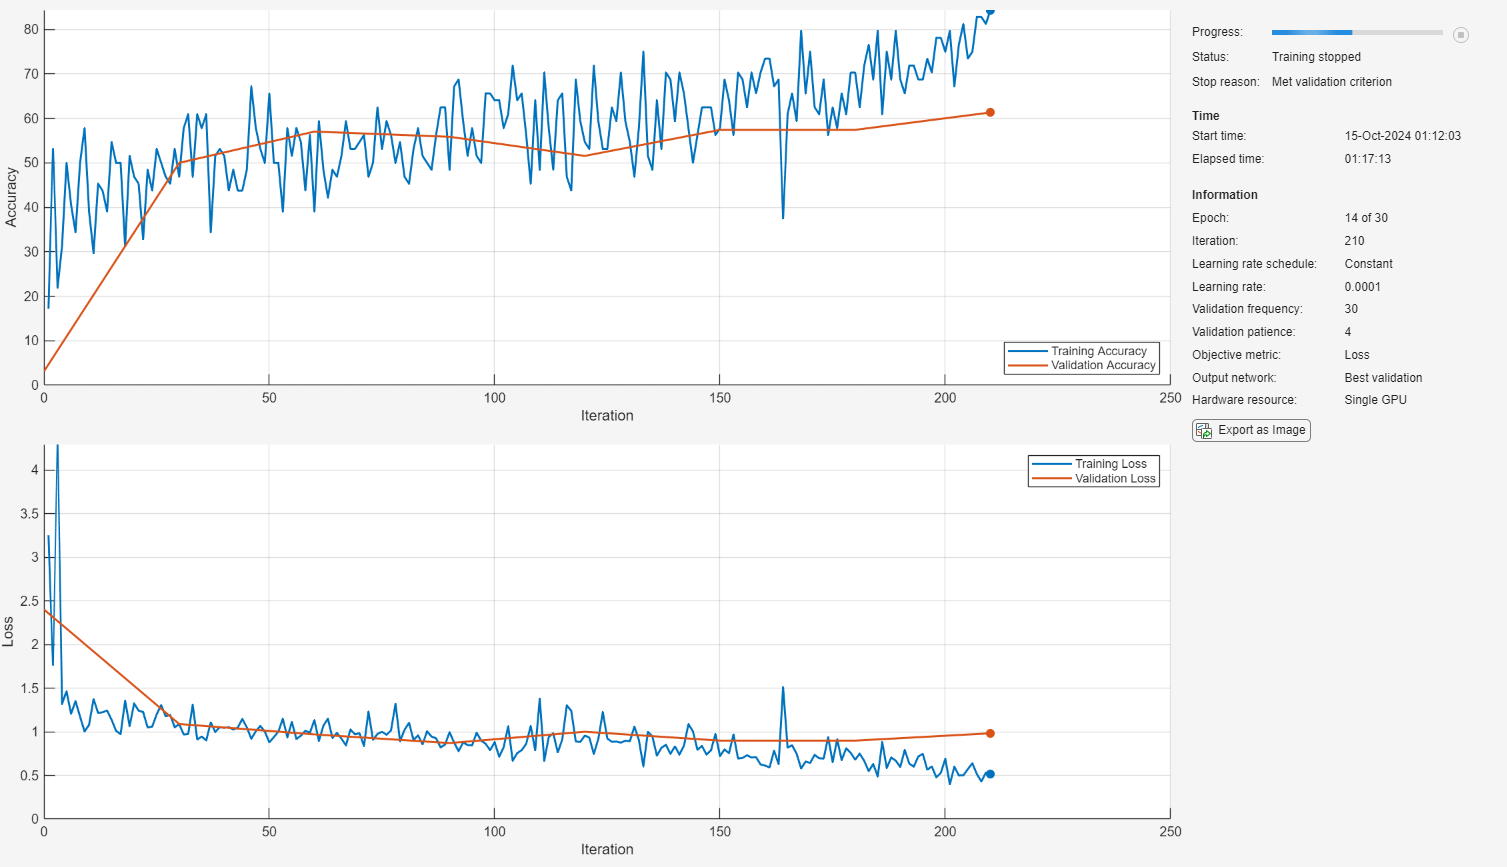

accuracy = 32.8320

classNames = categories(imdsTrain.Labels)
[~, predIdx] = max(singlePred);
predLabel = classes{predIdx};
disp(['Predict: ', predLabel]);